## **Worked Example 2.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the A, B, C and D matrices 
A = [0, 1; -1, -1];
B = [0; 1];
C = [1 0];
D = [0];

% Construct a state-space system
% using the ss(A, command)
sys = ss(A, B, C, D);


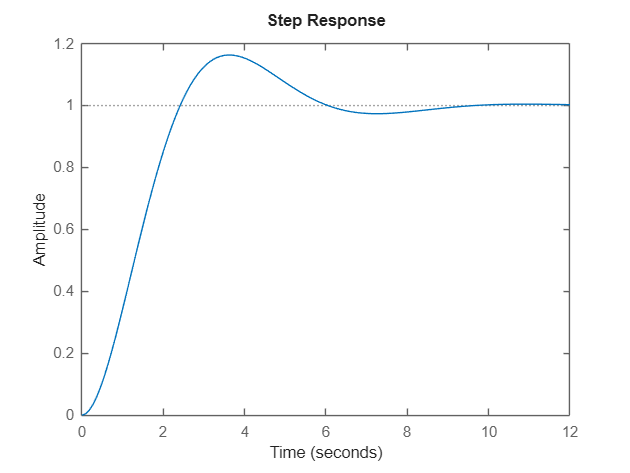

% Plot the step response of the system 
step(sys);

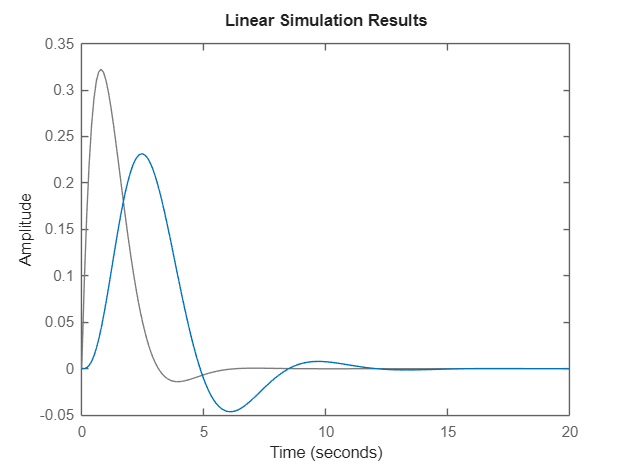

% Define the desired time interval T
% in this case T ranges from 0-20 seconds in intervals of 0.1 seconds
T = [0 : 0.1 : 20];

% Define the value of each input at each time interval
% in this case we have only one input f(t)
U = [(exp(-T) .* sin(T))];

% Define the initial condition of each of the states
% in this example we have two states
x0 = [0; 0];

% Simulate the dynamical system
lsim(sys, U, T, x0);

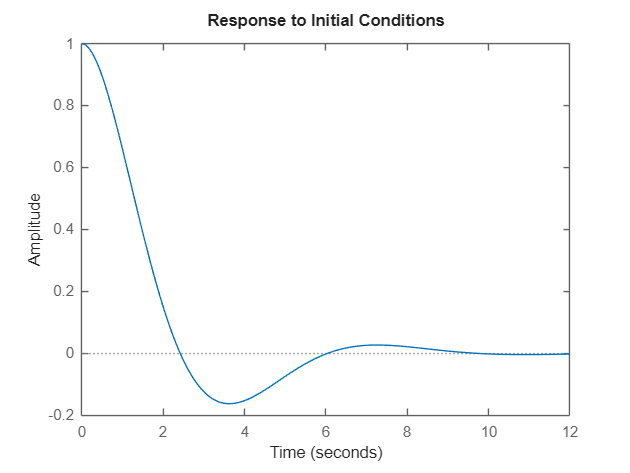

% Set the new initial conditions
x0 = [1; 0];

% Simulate the response from the initial conditions
initial(sys, x0);